clear; close all; clc;

## **1. Завантаження тестових зображень з бібліотеки MATLAB**

img1 = imread('cameraman.tif'); % Чорно-біле зображення
img2 = imread('peppers.png');  % Кольорове зображення

## 2. Відображення зображень на одному фреймі

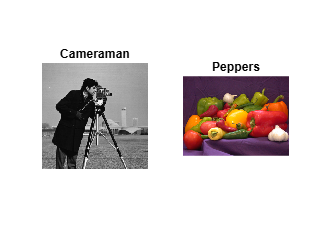

figure;
subplot(1,2,1), imshow(img1), title('Cameraman');
subplot(1,2,2), imshow(img2), title('Peppers');

## 3. Зашумлення зображення нормальним білим шумом і імпульсною перешкодою з різною щільністю.

noisy_gaussian_img1 = imnoise(img1, 'gaussian', 0, 0.01); % Білий шум(Gaussian noise) з дисперсією 0.01
noisy_sp_low_img1 = imnoise(img1, 'salt & pepper', 0.02); % імпульсна перешкода (Salt & Pepper) з щільність 0.02
noisy_sp_high_img1 = imnoise(img1, 'salt & pepper', 0.1); % імпульсна перешкода (Salt & Pepper) з щільність 0.1

noisy_gaussian_img2 = imnoise(img2, 'gaussian', 0, 0.05); % Білий шум(Gaussian noise) з дисперсією 0.05
noisy_sp_low_img2 = imnoise(img2, 'salt & pepper', 0.05); % імпульсна перешкода (Salt & Pepper) з щільність 0.05
noisy_sp_high_img2 = imnoise(img2, 'salt & pepper', 0.15); % імпульсна перешкода (Salt & Pepper) з щільність 0.15

## **4. Відображення зашумлених зображень**

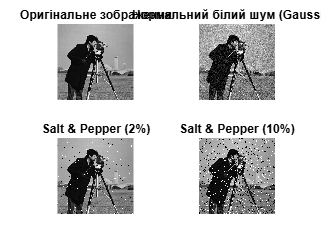

figure;
subplot(2,2,1), imshow(img1), title('Оригінальне зображення');
subplot(2,2,2), imshow(noisy_gaussian_img1), title('Нормальний білий шум (Gaussian)');
subplot(2,2,3), imshow(noisy_sp_low_img1), title('Salt & Pepper (2%)');
subplot(2,2,4), imshow(noisy_sp_high_img1), title('Salt & Pepper (10%)');

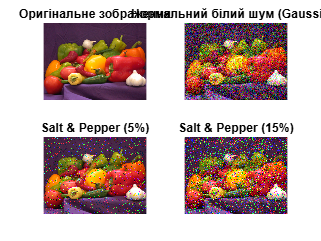

figure;
subplot(2,2,1), imshow(img2), title('Оригінальне зображення');
subplot(2,2,2), imshow(noisy_gaussian_img2), title('Нормальний білий шум (Gaussian)');
subplot(2,2,3), imshow(noisy_sp_low_img2), title('Salt & Pepper (5%)');
subplot(2,2,4), imshow(noisy_sp_high_img2), title('Salt & Pepper (15%)');

## **5. Фільтрація вихідних зображень лінійними фільтрами з використанням **

average -  низькочастотний 

gaussian - низькочастотний з гаусівською вагою

unsharp - фільтр підвищення різкості (високочастотний)

h_avg = fspecial('average', [3 3]); % 3x3 усереднювальний фільтр
h_gauss = fspecial('gaussian', [3 3], 0.5); % 3x3 гаусівський фільтр, sigma=0.5
h_unsharp= fspecial('unsharp'); % фільтр для підсилення різкості

% Gaussian noise
cam_gauss_avg = imfilter(noisy_gaussian_img1, h_avg);
cam_gauss_gauss = imfilter(noisy_gaussian_img1, h_gauss);
cam_gauss_unsharp = imfilter(noisy_gaussian_img1, h_unsharp);

% Salt & Pepper noise
cam_sp_avg = imfilter(noisy_sp_low_img1, h_avg);
cam_sp_gauss = imfilter(noisy_sp_low_img1, h_gauss);
cam_sp_unsharp = imfilter(noisy_sp_low_img1, h_unsharp);


% Gaussian noise
pep_gauss_avg = imfilter(noisy_gaussian_img2, h_avg);
pep_gauss_gauss = imfilter(noisy_gaussian_img2, h_gauss);
pep_gauss_unsharp = imfilter(noisy_gaussian_img2, h_unsharp);

% Salt & Pepper noise
pep_sp_avg = imfilter(noisy_sp_high_img2, h_avg);
pep_sp_gauss = imfilter(noisy_sp_high_img2, h_gauss);
pep_sp_unsharp = imfilter(noisy_sp_high_img2, h_unsharp);

## **6. Відображення зображень після фільтрації**

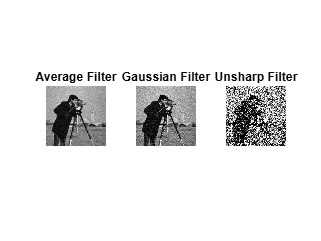

figure('Name','cameraman Gaussian Noise - Linear Filters');
subplot(1,3,1), imshow(cam_gauss_avg), title('Average Filter');
subplot(1,3,2), imshow(cam_gauss_gauss), title('Gaussian Filter');
subplot(1,3,3), imshow(cam_gauss_unsharp), title('Unsharp Filter');

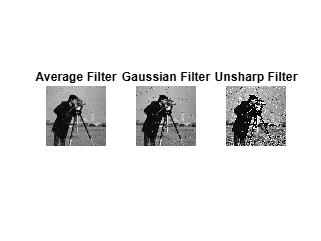


figure('Name','cameraman Salt & Pepper (2%) Noise - Linear Filters');
subplot(1,3,1), imshow(cam_sp_avg), title('Average Filter');
subplot(1,3,2), imshow(cam_sp_gauss), title('Gaussian Filter');
subplot(1,3,3), imshow(cam_sp_unsharp), title('Unsharp Filter');

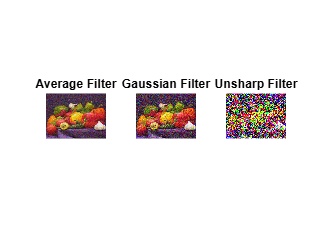


figure('Name','peppers Gaussian Noise - Linear Filters');
subplot(1,3,1), imshow(pep_gauss_avg), title('Average Filter');
subplot(1,3,2), imshow(pep_gauss_gauss), title('Gaussian Filter');
subplot(1,3,3), imshow(pep_gauss_unsharp), title('Unsharp Filter');

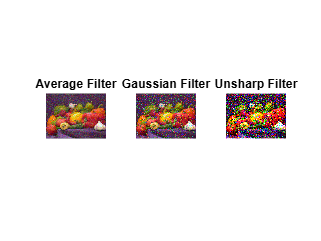


figure('Name','peppers Salt & Pepper (15%) Noise - Linear Filters');
subplot(1,3,1), imshow(pep_sp_avg), title('Average Filter');
subplot(1,3,2), imshow(pep_sp_gauss), title('Gaussian Filter');
subplot(1,3,3), imshow(pep_sp_unsharp), title('Unsharp Filter');

## 7. Адаптивна фільтрація wiener2

Wiener2 адаптивно підлаштовується до локальної дисперсії зображення. Для сірого зображення можна застосувати напряму, а для кольорового по каналах.

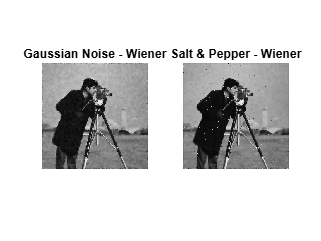

cam_gauss_wiener = wiener2(noisy_gaussian_img1, [5 5]);
cam_sp_wiener = wiener2(noisy_sp_low_img1,    [5 5]);

figure('Name','Cameraman - Wiener Filter');
subplot(1,2,1), imshow(cam_gauss_wiener), title('Gaussian Noise - Wiener');
subplot(1,2,2), imshow(cam_sp_wiener), title('Salt & Pepper - Wiener');


% Wiener2 оцінює локальні статистики (середнє, дисперсію) та зменшує шум
% ефективніше, ніж фіксований лінійний фільтр, особливо при нестаціонарних шумах.

## 8-9. Медіанна фільтрація

Медіанна фільтрація добре пригнічує імпульсні шуми, зберігаючи краї краще, ніж середнє згладжування.

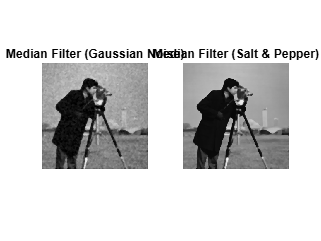

% Медіанна фільтрація зображень з різними типами шуму
median_img1 = medfilt2(noisy_gaussian_img1, [5 5]); % Медіанна фільтрація для Cameraman з білим шумом
median_img2 = medfilt2(noisy_sp_low_img1, [5 5]); % Медіанна фільтрація для Cameraman з імпульсною перешкодою

% Відображення результатів медіанної фільтрації
figure;
subplot(1,2,1), imshow(median_img1), title('Median Filter (Gaussian Noise)');
subplot(1,2,2), imshow(median_img2), title('Median Filter (Salt & Pepper)');